Load Data


hm_data_path = "Y:\usvi\stj\fishAuditing\HM_ST_comparison\HM_master_labels_TK\consolidated_data_HM_TK.txt";
st_data_path = "Y:\usvi\stj\fishAuditing\HM_ST_comparison\ST_master_labels_TK\consolidated_data_ST_TK.txt";
hm_raw = readtable(hm_data_path);
st_raw = readtable(st_data_path);


Total Annotations

Don't pay attention to this, use the excel version

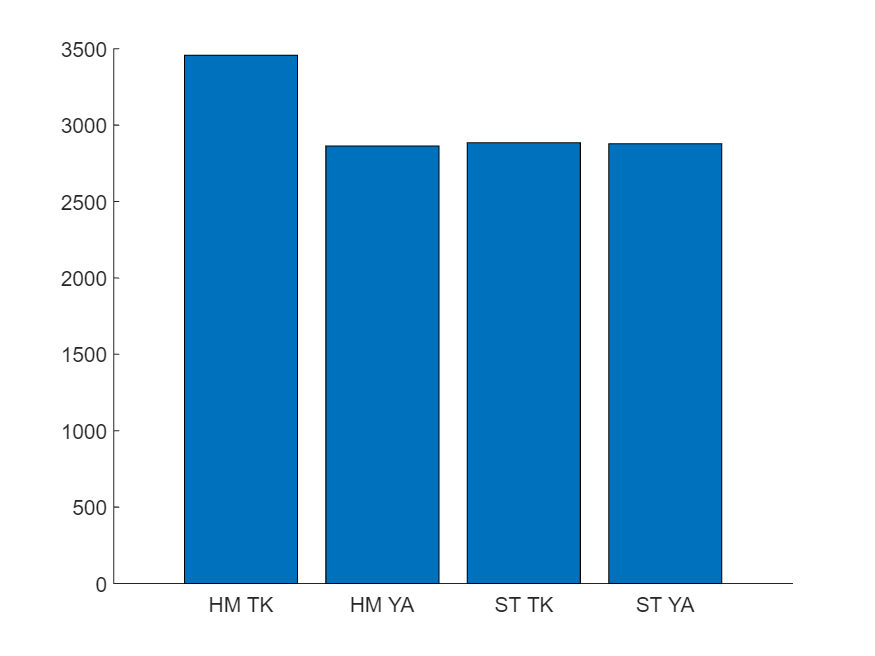

% sites = categorical(["HM TK", "ST TK", "HM YA", "ST YA"]);
% calls = [3458, 2885, 2864, 2878];
% 
% figure(1); clf; hold on
% bar(sites, calls);

% xticklabels = ["HM TK", "ST TK", "HM YA", "ST YA"]

xticklabels = 1×4 string array
    "HM TK"    "ST TK"    "HM YA"    "ST YA"


Call Rate Over Time of Day

Yawzi -- Generate call rate data

% select which data you want call rates for (e.g. full set, pulses, tonals)
hm_data = hm_raw;
st_data = st_raw;

hm_call_rates = zeros([1, 48]);
st_call_rates = zeros([1, 48]);
time_of_day = sort([0:10000:230000, 3000:10000:233000]);
i_time  = 1;
call_count = 0;

% go through HM data row by row to fill call rates matrix
for r = 1:height(hm_data)
    row = hm_data(r, :);
    time = time_of_day(i_time); % the minute we are looking at

    % check if that call is part of the same time and count it
    % note: currently only checking for time, not date or year
    if strcmp(row{1, 8}, 'boat')
        continue
    elseif time == row{1, 3} 
        call_count = call_count + 1;
    else
        % reset counters for next minute/half hour
        hm_call_rates(i_time) = call_count;
        call_count = 0;
        i_time = i_time + 1;
    end
end

hm_call_rates(i_time) = call_count; % fill in last datapoint
i_time = 1;

% go through ST data row by row to fill call rates matrix
for r = 1:height(st_data)
    row = st_data(r, :);
    time = time_of_day(i_time); % the minute we are looking at

    % check if that call is part of the same time and count it
    % note: currently only checking for time, not date or year
    if strcmp(row{1, 8}, 'boat')
        continue
    elseif time == row{1, 3} 
        call_count = call_count + 1;
    else
        % reset counters for next minute/half hour
        st_call_rates(i_time) = call_count;
        call_count = 0;
        i_time = i_time + 1;
    end
end

st_call_rates(i_time) = call_count;



Generate call rate plot

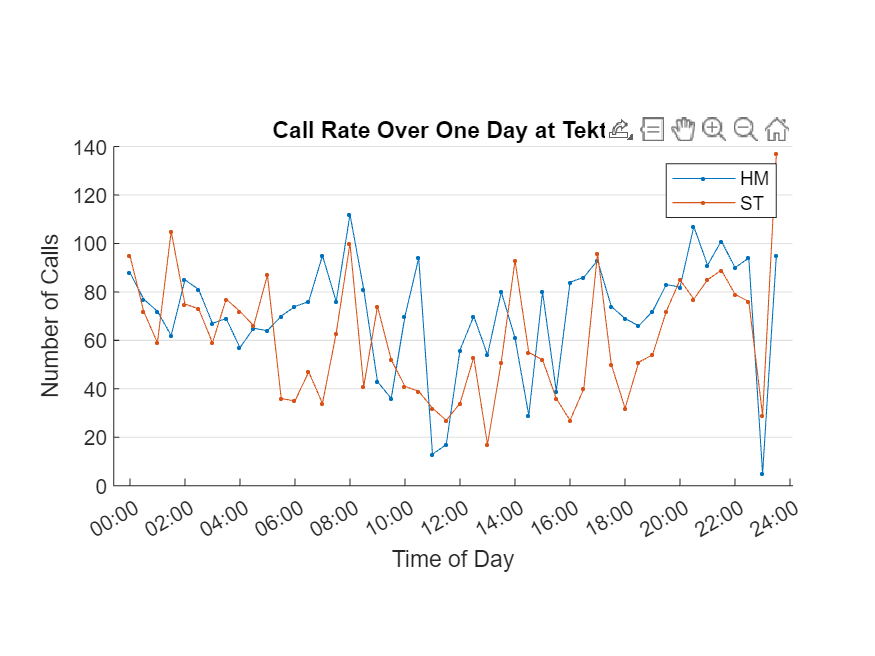

figure(1); clf; hold on

t = 0:hours(0.5):hours(23.5); % time of day array but in a nicer format

% hm_call_rates_percent = hm_call_rates / height(hm_data);
% st_call_rates_percent = st_call_rates / height(st_data);

plot(t, hm_call_rates, '.-', 'DurationTickFormat','hh:mm');
plot(t, st_call_rates, '.-', 'DurationTickFormat','hh:mm');
title('Call Rate Over One Day at Tektite');
xlabel('Time of Day');
ylabel('Number of Calls');
xticks(0:hours(2):hours(24));
set(gca, 'YGrid', 'on')
pbaspect([2 1 1]);
legend('HM', 'ST');

Create arrays with only one kind of call

% change text string to whatever label you want to pull out

hm_tonals = hm_raw(contains(hm_raw.Type, 'tonal'), :);
st_tonals = st_raw(contains(st_raw.Type, 'tonal'), :);


Compare bounding boxes

between folders A and B

A_unique = []; % holds annotations from A that don't have matching B. y by 1 array of 1x8 tables
B_unique = []; % holds annotations from A that don't have matching B. y by 1 array of 1x8 tables
same = []; % y by 2 array of 1x8 tables

a_folder = "Y:\usvi\stj\fishAuditing\HM_ST_comparison\HM_master_labels_TK";
b_folder = "Y:\usvi\stj\fishAuditing\HM_ST_comparison\ST_master_labels_TK";

% gets all files from the folder specified
a_files_dirty = dir(fullfile(a_folder, '*.txt'));
b_files_dirty = dir(fullfile(b_folder, '*.txt'));

% creates struct with only the label files (removes anything else)
a_files = [];
b_files = [];

for i=(1:length(a_files_dirty))
    if contains(a_files_dirty(i).name, 'label')
        a_files = [a_files; a_files_dirty(i, :)];
    end
end
for i=(1:length(b_files_dirty))
    if contains(b_files_dirty(i).name, 'label')
        b_files = [b_files; b_files_dirty(i, :)];
    end
end
% can potentially go back and delete the files_dirty vars later (for
% workspace cleanliness)


% check if we have the same number of label files in both folders, else
% display error
if height(a_files) == height(b_files)
    
    % iterates through each file, which corresponds with each time period
    for f = 1:length(a_files)
        a_data = readtable(fullfile(a_folder, a_files(f).name));
        b_data = readtable(fullfile(b_folder, b_files(f).name));

        a_data = a_data(2:end, :); % remove header row (same between all files)
        b_data = b_data(2:end, :);

        [year, date, time] = extract_file_data(a_files(f).name); % get year, date, time
        metadata = repmat([year, date, time], [height(a_data), 1]); % format data table to include "metadata"
        a_data = [array2table(metadata), a_data];
        metadata = repmat([year, date, time], [height(b_data), 1]);
        b_data = [array2table(metadata), b_data];

        if width(b_data) > 8
            b_data = b_data(:, 1:8);
        end

        a_data = renamevars(a_data,a_data.Properties.VariableNames, ["Year", "Date", "Hour", "Start_Time", "End_Time", "Low_Freq", "High_Freq", "Type"]);
        b_data = renamevars(b_data,b_data.Properties.VariableNames, ["Year", "Date", "Hour", "Start_Time", "End_Time", "Low_Freq", "High_Freq", "Type"]);

        a_full_clean = a_data;
        b_full_clean = b_data;

        b_i = 1; % index for which row of b we're looking at

        % keep doing this until you've gone through the entire file
        while ~isempty(a_data)            
            % check if there are still entries in b; when b is done, move any remaining calls in A to the unique calls
            if isempty(b_data)
               A_unique = [A_unique; a_data(1,:)];
               a_data(1,:) = []; % remove row from a_data once it's been added to unique list
            elseif b_i > height(b_data)
               A_unique = [A_unique; a_data(1,:)];
               a_data(1,:) = [];
               B_unique = [B_unique; b_data(1,:)];
               b_data(1,:) = [];
            else
               time_diff = a_data{1, 4} - b_data{b_i, 4}; % compare start times
               
               % start times are close enough
               if abs(time_diff) <= 0.5
                   freq_diff = a_data{1, 6} - b_data{b_i, 6}; % compare lower frequencies
                   
                   % same call
                   if abs(freq_diff) <= 100 && call_type_match(a_data{1,8}{1}, b_data{b_i,8}{1})
                       % move both calls to the same array and remove
                       % appropriate rows from datatables
                       same = [same; [{a_data(1,:)}, {b_data(b_i,:)}]];
                       a_data(1,:) = [];
                       b_data(b_i,:) = [];
                   % same time but not the same frequency or call type
                   else
                       % look at the next row of b
                       b_i = b_i + 1;
                   end
                   
               elseif time_diff > 0 % b time is too small (out of range on low end)
                   
                   % move b to unique list
                   B_unique = [B_unique; b_data(b_i,:)];
                   b_data(b_i,:) = [];
                   b_i = 1; % reset b index to first row
               elseif time_diff < 0
                   
                   % move a to unique list
                   A_unique = [A_unique; a_data(1,:)];
                   a_data(1,:) = [];
                   b_i = 1; % reset b index to first row
               end
            end 
        end

        % once there are no entries in a, move anything remaining in b to
        % B_unique.
        while isempty(a_data) && ~isempty(b_data)
            B_unique = [B_unique; b_data(1,:)];
            b_data(1,:) = [];
        end
    end
else
    error('Inconsistent number of label files between the two folders')
end



function [year, date, time] = extract_file_data(name)

    if name(1) == '2'
        type = 'HM';
    elseif name(1) == '6'
        type = 'ST';
    else
        error('Not recognized as HydroMoth or SoundTrap')
    end

    if type == "HM"
        year = str2double(name(3:4));
        date = str2double(name(5:8));
        title_time = str2double(name(10:15)); 
        if title_time < 40000 % adjust for HM time difference
            time = title_time + 200000; % handle case where it's gone past midnight
        else
            time = title_time - 40000; % handle normal case (of being 4 hours ahead)
        end
    elseif type == "ST"
        year = str2double(name(6:7));
        date = str2double(name(9:11));
        time = str2double(name(12:17));
    end

end

function result = call_type_match(str1, str2)

    if contains(str1, 'pulse') && contains(str2, 'pulse')
        result = true;
    elseif contains(str1, 'tonal') && contains(str2, 'tonal')
        result = true;
    else
        result = false;
    end
end